# Sessió 12 - Exercici

### Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

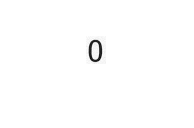

clear all
close all

model0 = imread("esun0_3.tif");
model1 = imread("esun1_2.tif");
imshow(model0)

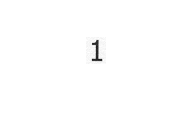

figure, imshow(model1)

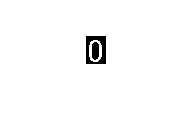


% Binarització
th_model0 = graythresh(model0);
model0 = 1-imbinarize(model0, th_model0);

th_model1 = graythresh(model1);
model1 = 1-imbinarize(model1, th_model1);

imshow(model0)

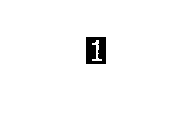

figure, imshow(model1)

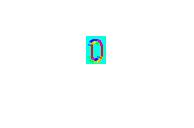



% Prova agafar només contorn
% ee = strel('disk', 1);
% dilate_mod0 = imdilate(model0, ee)
% dilate_mod0 = imsubtract(dilate_mod0, model0);
% figure, imshow(dilate_mod0)
% erode_mod0 = imerode(model0, ee)
% erode_mod0 = imsubtract(erode_mod0, model0);
% 
% figure, imshow(erode_mod0)
% res = imsubtract(double(dilate_mod0), double(erode_mod0));
% figure, imshow(res)




% Preparem el kernel
sob = fspecial("sobel");
soby = sob/4;
sobx = soby';

% Convolució
grady_model0 = imfilter(double(model0), soby, 'conv');
gradx_model0 = imfilter(double(model0), sobx, 'conv');

grady_model1 = imfilter(double(model1), soby, 'conv');
gradx_model1 = imfilter(double(model1), sobx, 'conv');

arg_model0 = atan2(grady_model0, gradx_model0);
arg_model1 = atan2(grady_model1, gradx_model1);

% max(arg(:))

angle_model0 = uint8((arg_model0+pi)/2/pi*254);
angle_model1 = uint8((arg_model1+pi)/2/pi*254);

figure,imshow(angle_model0),colormap('hsv')

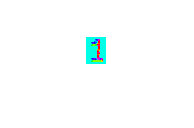

figure,imshow(angle_model1),colormap('hsv')

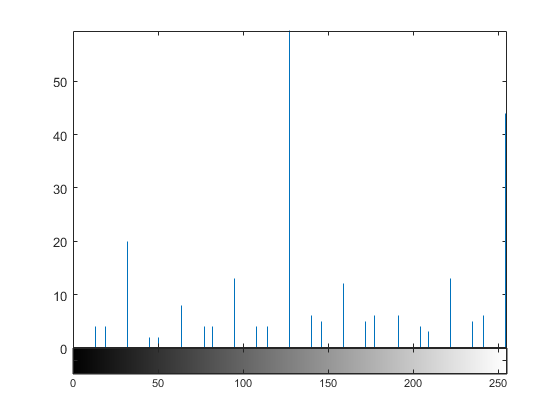


figure, imhist(angle_model0)

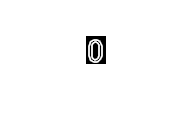

mod = sqrt(gradx_model0.^2+grady_model0.^2);
figure, imshow(mod, [])

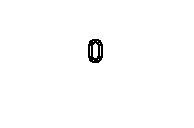

mask = (mod==0);
figure,imshow(mask)

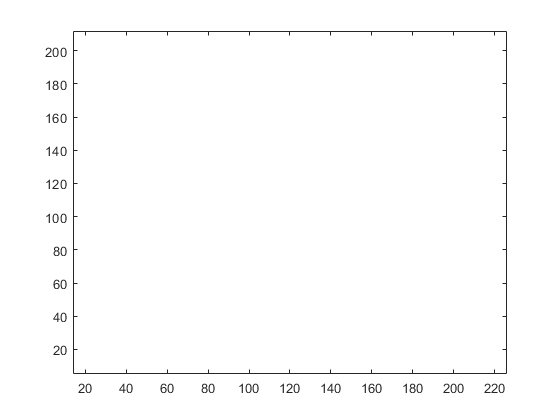

angle(mask) = 255;
h = imhist(angle);
hog = h(1:end-1);
figure, bar(hog)